
% Defining variables
    T=8

T = 8

    F=4096       % Sampling frequency (2^12)

F = 4096

    t=0:1/F:T    % Time from 0-8s in 4096 steps  

t =          0    0.0002    0.0005    0.0007    0.0010    0.0012    0.0015    0.0017    0.0020    0.0022    0.0024    0.0027    0.0029    0.0032    0.0034    0.0037    0.0039    0.0042    0.0044    0.0046    0.0049    0.0051    0.0054    0.0056    0.0059    0.0061    0.0063    0.0066    0.0068    0.0071    0.0073    0.0076    0.0078    0.0081    0.0083    0.0085    0.0088    0.0090    0.0093    0.0095    0.0098    0.0100    0.0103    0.0105    0.0107    0.0110    0.0112    0.0115    0.0117    0.0120


    v_t = abs(sin(pi*t)) + 2*sin(3*pi*t) + 3*sin(6*pi*t)    % orignal input of the circuit

v_t =          0    0.0192    0.0383    0.0575    0.0767    0.0959    0.1150    0.1342    0.1534    0.1725    0.1917    0.2109    0.2300    0.2492    0.2683    0.2874    0.3066    0.3257    0.3448    0.3640    0.3831    0.4022    0.4213    0.4404    0.4595    0.4785    0.4976    0.5167    0.5357    0.5548    0.5738    0.5928    0.6119    0.6309    0.6499    0.6689    0.6878    0.7068    0.7257    0.7447    0.7636    0.7825    0.8014    0.8203    0.8392    0.8581    0.8769    0.8957    0.9146    0.9334


    len=length(v_t) % Length of the input signal

len = 32769

    f=linspace(-F/2,F/2,len) % array of frequency values

f = 1.0e+03 *

   -2.0480   -2.0479   -2.0478   -2.0476   -2.0475   -2.0474   -2.0473   -2.0471   -2.0470   -2.0469   -2.0467   -2.0466   -2.0465   -2.0464   -2.0463   -2.0461   -2.0460   -2.0459   -2.0457   -2.0456   -2.0455   -2.0454   -2.0452   -2.0451   -2.0450   -2.0449   -2.0448   -2.0446   -2.0445   -2.0444   -2.0442   -2.0441   -2.0440   -2.0439   -2.0438   -2.0436   -2.0435   -2.0434   -2.0433   -2.0431   -2.0430   -2.0429   -2.0427   -2.0426   -2.0425   -2.0424   -2.0423   -2.0421   -2.0420   -2.0419


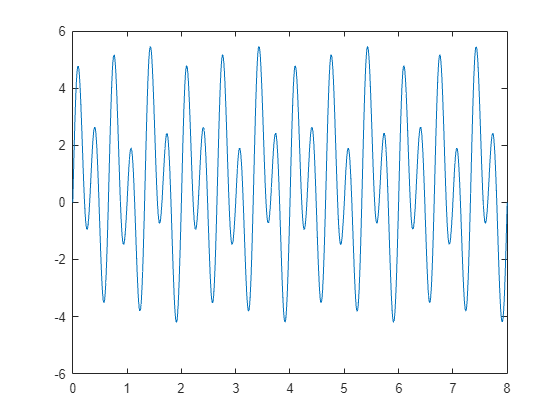




%Task i) plotting v(t)

    plot(t,v_t)

    %xlabel('Time, t (seconds)')
    %ylabel('Input Voltage, V(t) (Volts)')
    %grid on
    %title('Input Voltage vs Time graph (range 0<=t<=8)')

%task ii) plot amplitude-frequency response of v(t)

    v_f = fftshift(fft(v_t)) %fast fourier transform

v_f = 1.0e+04 *

  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i


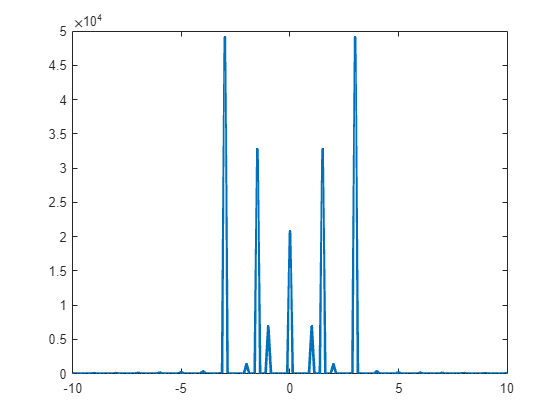

    
    plot(f,abs(v_f),"LineWidth",2)  %plotting the absolute value of v_f against frequency
    xlim([-10 10]) %limiting x axis to make data readable

    %xlabel('Frequency (Hz)')
    %ylabel('|V(f)|')
    %grid on
    %title('|V(f)| vs Frequency graph')
    


%task iii) plot amplitude-frequency response of circuit

%Definining variables
    s=1j*2*pi*f     %Redefining s so we can convert from laplace transforms to fourier transforms

s = 1.0e+04 *

   0.0000 - 1.2868i   0.0000 - 1.2867i   0.0000 - 1.2866i   0.0000 - 1.2866i   0.0000 - 1.2865i   0.0000 - 1.2864i   0.0000 - 1.2863i   0.0000 - 1.2862i   0.0000 - 1.2862i   0.0000 - 1.2861i   0.0000 - 1.2860i   0.0000 - 1.2859i   0.0000 - 1.2859i   0.0000 - 1.2858i   0.0000 - 1.2857i   0.0000 - 1.2856i   0.0000 - 1.2855i   0.0000 - 1.2855i   0.0000 - 1.2854i   0.0000 - 1.2853i   0.0000 - 1.2852i   0.0000 - 1.2851i   0.0000 - 1.2851i   0.0000 - 1.2850i   0.0000 - 1.2849i   0.0000 - 1.2848i   0.0000 - 1.2848i   0.0000 - 1.2847i   0.0000 - 1.2846i   0.0000 - 1.2845i   0.0000 - 1.2844i   0.0000 - 1.2844i   0.0000 - 1.2843i   0.0000 - 1.2842i   0.0000 - 1.2841i   0.0000 - 1.2840i   0.0000 - 1.2840i   0.0000 - 1.2839i   0.0000 - 1.2838i   0.0000 - 1.2837i   0.0000 - 1.2837i   0.0000 - 1.2836i   0.0000 - 1.2835i   0.0000 - 1.2834i   0.0000 - 1.2833i   0.0000 - 1.2833i   0.0000 - 1.2832i   0.0000 - 1.2831i   0.0000 - 1.2830i   0.0000 - 1.2829i


    R_1=1

R_1 = 1

    R_2=2

R_2 = 2

    L=0.1*s

L = 1.0e+03 *

   0.0000 - 1.2868i   0.0000 - 1.2867i   0.0000 - 1.2866i   0.0000 - 1.2866i   0.0000 - 1.2865i   0.0000 - 1.2864i   0.0000 - 1.2863i   0.0000 - 1.2862i   0.0000 - 1.2862i   0.0000 - 1.2861i   0.0000 - 1.2860i   0.0000 - 1.2859i   0.0000 - 1.2859i   0.0000 - 1.2858i   0.0000 - 1.2857i   0.0000 - 1.2856i   0.0000 - 1.2855i   0.0000 - 1.2855i   0.0000 - 1.2854i   0.0000 - 1.2853i   0.0000 - 1.2852i   0.0000 - 1.2851i   0.0000 - 1.2851i   0.0000 - 1.2850i   0.0000 - 1.2849i   0.0000 - 1.2848i   0.0000 - 1.2848i   0.0000 - 1.2847i   0.0000 - 1.2846i   0.0000 - 1.2845i   0.0000 - 1.2844i   0.0000 - 1.2844i   0.0000 - 1.2843i   0.0000 - 1.2842i   0.0000 - 1.2841i   0.0000 - 1.2840i   0.0000 - 1.2840i   0.0000 - 1.2839i   0.0000 - 1.2838i   0.0000 - 1.2837i   0.0000 - 1.2837i   0.0000 - 1.2836i   0.0000 - 1.2835i   0.0000 - 1.2834i   0.0000 - 1.2833i   0.0000 - 1.2833i   0.0000 - 1.2832i   0.0000 - 1.2831i   0.0000 - 1.2830i   0.0000 - 1.2829i


    C=2./s

C =    0.0000 + 0.0002i   0.0000 + 0.0002i   0.0000 + 0.0002i   0.0000 + 0.0002i   0.0000 + 0.0002i   0.0000 + 0.0002i   0.0000 + 0.0002i   0.0000 + 0.0002i   0.0000 + 0.0002i   0.0000 + 0.0002i   0.0000 + 0.0002i   0.0000 + 0.0002i   0.0000 + 0.0002i   0.0000 + 0.0002i   0.0000 + 0.0002i   0.0000 + 0.0002i   0.0000 + 0.0002i   0.0000 + 0.0002i   0.0000 + 0.0002i   0.0000 + 0.0002i   0.0000 + 0.0002i   0.0000 + 0.0002i   0.0000 + 0.0002i   0.0000 + 0.0002i   0.0000 + 0.0002i   0.0000 + 0.0002i   0.0000 + 0.0002i   0.0000 + 0.0002i   0.0000 + 0.0002i   0.0000 + 0.0002i   0.0000 + 0.0002i   0.0000 + 0.0002i   0.0000 + 0.0002i   0.0000 + 0.0002i   0.0000 + 0.0002i   0.0000 + 0.0002i   0.0000 + 0.0002i   0.0000 + 0.0002i   0.0000 + 0.0002i   0.0000 + 0.0002i   0.0000 + 0.0002i   0.0000 + 0.0002i   0.0000 + 0.0002i   0.0000 + 0.0002i   0.0000 + 0.0002i   0.0000 + 0.0002i   0.0000 + 0.0002i   0.0000 + 0.0002i   0.0000 + 0.0002i   0.0000 + 0.0002i


    
    ZP=2./(s+1)

ZP =    0.0000 + 0.0002i   0.0000 + 0.0002i   0.0000 + 0.0002i   0.0000 + 0.0002i   0.0000 + 0.0002i   0.0000 + 0.0002i   0.0000 + 0.0002i   0.0000 + 0.0002i   0.0000 + 0.0002i   0.0000 + 0.0002i   0.0000 + 0.0002i   0.0000 + 0.0002i   0.0000 + 0.0002i   0.0000 + 0.0002i   0.0000 + 0.0002i   0.0000 + 0.0002i   0.0000 + 0.0002i   0.0000 + 0.0002i   0.0000 + 0.0002i   0.0000 + 0.0002i   0.0000 + 0.0002i   0.0000 + 0.0002i   0.0000 + 0.0002i   0.0000 + 0.0002i   0.0000 + 0.0002i   0.0000 + 0.0002i   0.0000 + 0.0002i   0.0000 + 0.0002i   0.0000 + 0.0002i   0.0000 + 0.0002i   0.0000 + 0.0002i   0.0000 + 0.0002i   0.0000 + 0.0002i   0.0000 + 0.0002i   0.0000 + 0.0002i   0.0000 + 0.0002i   0.0000 + 0.0002i   0.0000 + 0.0002i   0.0000 + 0.0002i   0.0000 + 0.0002i   0.0000 + 0.0002i   0.0000 + 0.0002i   0.0000 + 0.0002i   0.0000 + 0.0002i   0.0000 + 0.0002i   0.0000 + 0.0002i   0.0000 + 0.0002i   0.0000 + 0.0002i   0.0000 + 0.0002i   0.0000 + 0.0002i


    ZS=1+0.1*s

ZS = 1.0e+03 *

   0.0010 - 1.2868i   0.0010 - 1.2867i   0.0010 - 1.2866i   0.0010 - 1.2866i   0.0010 - 1.2865i   0.0010 - 1.2864i   0.0010 - 1.2863i   0.0010 - 1.2862i   0.0010 - 1.2862i   0.0010 - 1.2861i   0.0010 - 1.2860i   0.0010 - 1.2859i   0.0010 - 1.2859i   0.0010 - 1.2858i   0.0010 - 1.2857i   0.0010 - 1.2856i   0.0010 - 1.2855i   0.0010 - 1.2855i   0.0010 - 1.2854i   0.0010 - 1.2853i   0.0010 - 1.2852i   0.0010 - 1.2851i   0.0010 - 1.2851i   0.0010 - 1.2850i   0.0010 - 1.2849i   0.0010 - 1.2848i   0.0010 - 1.2848i   0.0010 - 1.2847i   0.0010 - 1.2846i   0.0010 - 1.2845i   0.0010 - 1.2844i   0.0010 - 1.2844i   0.0010 - 1.2843i   0.0010 - 1.2842i   0.0010 - 1.2841i   0.0010 - 1.2840i   0.0010 - 1.2840i   0.0010 - 1.2839i   0.0010 - 1.2838i   0.0010 - 1.2837i   0.0010 - 1.2837i   0.0010 - 1.2836i   0.0010 - 1.2835i   0.0010 - 1.2834i   0.0010 - 1.2833i   0.0010 - 1.2833i   0.0010 - 1.2832i   0.0010 - 1.2831i   0.0010 - 1.2830i   0.0010 - 1.2829i



    
    H_f=ZP./(ZP+ZS) %Determining the value of H(f)

H_f =   -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i


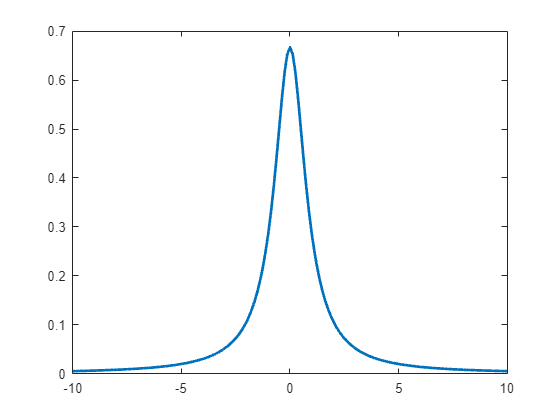

    
    plot(f,abs(H_f),"LineWidth",2)
    xlim([-10 10])

    %xlabel('Frequency (Hz)')
    %ylabel('|H(f)|')
    %grid on
    %title('|H(f)| vs Frequency graph')
    %xlim([-10 10]) %limiting x axis to make data readable

%Task iv) plot voltage accross R2 (t=0 to t=infty)

    V_R2_f=H_f.*v_f     %determining a frequency domain value for voltage across R2

V_R2_f = 1.0e+04 *

   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i


    v_R2_t=ifft(ifftshift(V_R2_f))      %Converting this back to the time domain equivalent

v_R2_t =     0.0731    0.0719    0.0707    0.0696    0.0684    0.0672    0.0660    0.0648    0.0637    0.0625    0.0613    0.0602    0.0590    0.0579    0.0567    0.0556    0.0544    0.0533    0.0521    0.0510    0.0499    0.0487    0.0476    0.0465    0.0454    0.0443    0.0432    0.0421    0.0410    0.0399    0.0388    0.0377    0.0366    0.0355    0.0344    0.0333    0.0322    0.0312    0.0301    0.0290    0.0280    0.0269    0.0259    0.0248    0.0238    0.0227    0.0217    0.0207    0.0196    0.0186


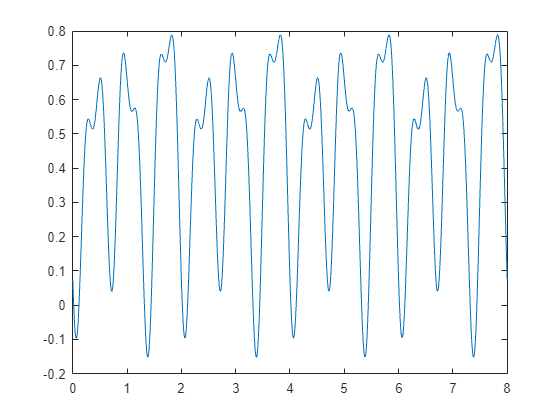


    plot(t,v_R2_t)

    %xlabel('Time(s)')
    %ylabel('Voltage(V)')
    %grid on
    %title('R2 Voltage vs time graph (Constant input)')


%task v) plot voltage accross R2 (input voltage turns off at t=4)

    v2_t=v_t.*(heaviside(t)-heaviside(t-4))         %Defining a new input voltage that 

v2_t =          0    0.0192    0.0383    0.0575    0.0767    0.0959    0.1150    0.1342    0.1534    0.1725    0.1917    0.2109    0.2300    0.2492    0.2683    0.2874    0.3066    0.3257    0.3448    0.3640    0.3831    0.4022    0.4213    0.4404    0.4595    0.4785    0.4976    0.5167    0.5357    0.5548    0.5738    0.5928    0.6119    0.6309    0.6499    0.6689    0.6878    0.7068    0.7257    0.7447    0.7636    0.7825    0.8014    0.8203    0.8392    0.8581    0.8769    0.8957    0.9146    0.9334


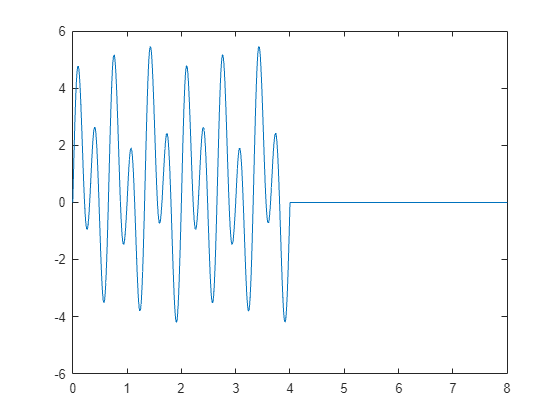

                        % is the same as the previous one but it turns off at t=4

    plot(t,v2_t)        %This is a plot of the new input voltage.

    %xlabel('Time, t (seconds)')
    %ylabel('Input Voltage, V(t) (Volts)')
    %grid on
    %title('Input Voltage vs Time graph (range 0<=t<=8) for Task 5')

    v2_f=fft(v2_t)  %Finding the new input's FFT

v2_f = 1.0e+04 *

   1.0430 + 0.0000i   0.3057 - 0.6715i  -0.0000 - 0.0000i   0.3179 - 0.2468i  -0.0000 - 0.0001i   0.3467 - 0.1919i  -0.0001 - 0.0001i   0.4061 - 0.3050i  -0.3477 - 0.0003i   0.5490 + 0.1553i   0.0000 - 0.0003i   1.2531 + 0.0171i   0.0009 - 1.6385i  -0.8172 - 0.0118i  -0.0000 + 0.0002i  -0.0951 - 0.0482i  -0.0695 - 0.0001i   0.0890 + 0.0370i   0.0000 - 0.0001i   0.2339 + 0.0052i   0.0000 - 0.0003i   0.4719 - 0.0036i  -0.0000 - 0.0008i   1.5317 - 0.0179i  -0.0270 - 2.4576i  -1.5859 + 0.0147i   0.0000 + 0.0010i  -0.5338 + 0.0017i  -0.0000 + 0.0005i  -0.3194 - 0.0025i  -0.0000 + 0.0004i  -0.2257 - 0.0110i  -0.0166 + 0.0003i  -0.1729 + 0.0091i   0.0000 + 0.0003i  -0.1389 + 0.0012i  -0.0000 + 0.0002i  -0.1151 - 0.0015i  -0.0000 + 0.0002i  -0.0976 - 0.0069i  -0.0105 + 0.0002i  -0.0843 + 0.0059i   0.0000 + 0.0002i  -0.0737 + 0.0008i  -0.0000 + 0.0001i  -0.0651 - 0.0010i  -0.0000 + 0.0001i  -0.0581 - 0.0047i  -0.0073 + 0.0001i  -0.0523 + 0.0041i


    Y2_f=H_f.*(fftshift(v2_f))      %determining a frequency domain value for voltage across R2 

Y2_f = 1.0e+03 *

   0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i


    y2_t=ifft(ifftshift(Y2_f))       %Converting this back to the time domain equivalent

y2_t =    -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0004


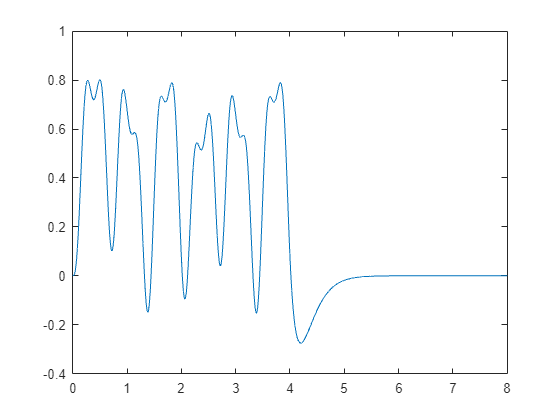

    
    plot(t,y2_t)

    %xlabel('Time(s)')
    %ylabel('Voltage(V)')
    %grid on
    %title('R2 Voltage vs time graph (Input moved at t=4)')
    %grid on


